% This code creates tow datastores (training and validation), uploads
% Alexnet, makes desired adjustments, trains the network, classifies the
% datasets and determines confusion matrices, ROC curves and relevant
% metrics for both training and validation datasets.

% Based on MathWork's example: https://es.mathworks.com/help/deeplearning/ug/transfer-learning-using-alexnet.html
% 
clear
clc

## Preparation of the training and validation datastores


imdsTrain = imageDatastore('C:\Users\pablosangil\Downloads\Datasets\Covid-19 RD Final\alexnet\Train','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('C:\Users\pablosangil\Downloads\Datasets\Covid-19 RD Final\alexnet\Validation','IncludeSubfolders',true,'LabelSource','foldernames');


## Uploading Neural Network


net = alexnet;
%analyzeNetwork(net)
inputSize = net.Layers(1).InputSize;
layersTransfer = net.Layers(1:end-3);
numClasses = numel(categories(imdsTrain.Labels));
layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];
%layers(1:10) = freezeWeights(layers(1:10));


## Data Augmentation with spatial transformations


pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

## Training options


options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Initialize training and classification


netTransfer = trainNetwork(augimdsTrain,layers,options);

[YPred,scores] = classify(netTransfer,augimdsValidation);
idx = randperm(numel(imdsValidation.Files),4);
save('my_alexnet.mat','netTransfer')



## Confusion matrix and metrics of validation data

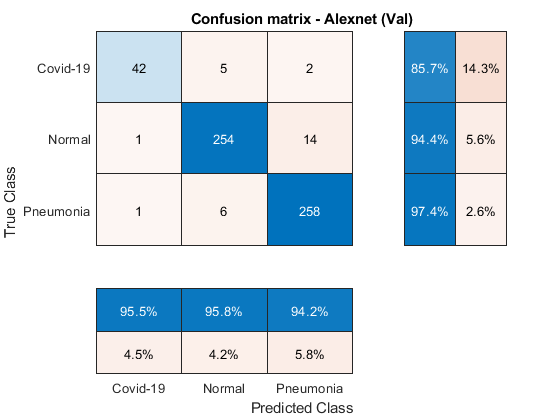

figure

cm=confusionchart(imdsValidation.Labels,YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
title('Confusion matrix - Alexnet (Val)');

metricas(cm)

ans = struct with fields:
        Accuracy: 95.0257
       Precision: [95.4545 95.8491 94.1606]
    Sensibilidad: [85.7143 94.4238 97.3585]
       F_measure: [90.3226 95.1311 95.7328]
       G_measure: [90.4534 95.1338 95.7462]
    F_measureTot: 93.8080
    G_measureTot: 93.8174


## ROC curve and AUC of vlidation data

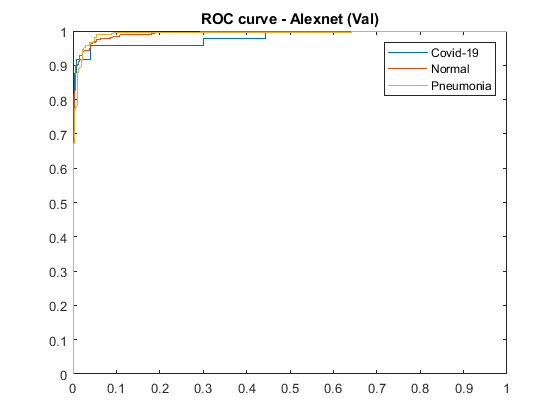

[Xco,Yco,Tco,AUCco] = perfcurve(imdsValidation.Labels,scores(:,1),'Covid-19');
[Xno,Yno,Tno,AUCno] = perfcurve(imdsValidation.Labels,scores(:,2),'Normal');
[Xpn,Ypn,Tpn,AUCpn] = perfcurve(imdsValidation.Labels,scores(:,3),'Pneumonia');

figure
plot(Xco,Yco)
hold on
plot(Xno,Yno)
plot(Xpn,Ypn)

hold off

legend('Covid-19','Normal','Pneumonia')
title('ROC curve - Alexnet (Val)')


auc_text='AUC = %f\n';
fprintf(auc_text,AUCco,AUCno,AUCpn);

AUC = 0.982152
AUC = 0.993299
AUC = 0.992560


## Classification of training dataset


[YPred,scores] = classify(netTransfer,augimdsTrain);
idx = randperm(numel(imdsTrain.Files),4);


## Confusion matrix and metrics of training dataset

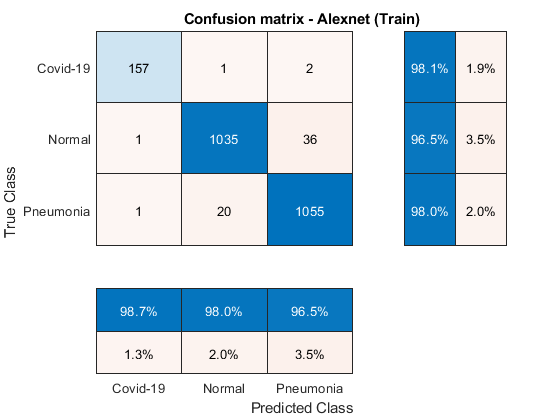

figure

cm=confusionchart(imdsTrain.Labels,YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
title('Confusion matrix - Alexnet (Train)');

metricas(cm)

ans = struct with fields:
        Accuracy: 97.3570
       Precision: [98.7421 98.0114 96.5233]
    Sensibilidad: [98.1250 96.5485 98.0483]
       F_measure: [98.4326 97.2744 97.2799]
       G_measure: [98.4331 97.2772 97.2828]
    F_measureTot: 97.6664
    G_measureTot: 97.6664


## ROC curve and AUC of training dataset

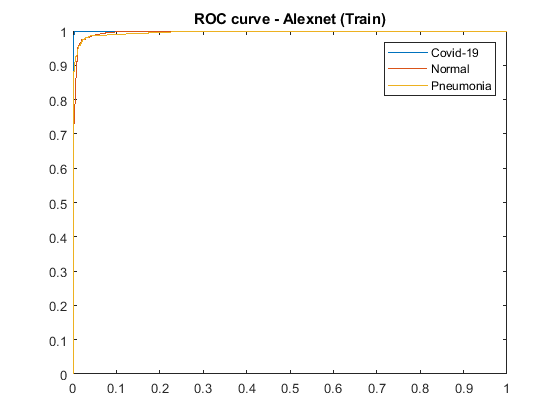


[Xco,Yco,Tco,AUCco] = perfcurve(imdsTrain.Labels,scores(:,1),'Covid-19');
[Xno,Yno,Tno,AUCno] = perfcurve(imdsTrain.Labels,scores(:,2),'Normal');
[Xpn,Ypn,Tpn,AUCpn] = perfcurve(imdsTrain.Labels,scores(:,3),'Pneumonia');

figure
plot(Xco,Yco)
hold on
plot(Xno,Yno)
plot(Xpn,Ypn)

hold off

legend('Covid-19','Normal','Pneumonia')
title('ROC curve - Alexnet (Train)')


auc_text='AUC = %f\n';
fprintf(auc_text,AUCco,AUCno,AUCpn);

AUC = 0.999913
AUC = 0.996315
AUC = 0.996101
